# Test CNN2D optimization, training and Testing

# Test XAI Methods similar to [https://ieeexplore.ieee.org/document/10175975](https://ieeexplore.ieee.org/document/10175975) However different dataset was used therefore differen results

## Load the Szenario or build from scratch

clearvars;
%LoadToolbox
addPaths;

%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

% If multiple Sensors should be used
%loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat']);convertCharsToStrings([locationData 'sensorB.mat'])];
%loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat']);convertCharsToStrings([locationData 'target.mat'])];

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 1;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Not the exact split is performed than in the original data (~20 UGMs less in test Set)
[data,target] = loadDataFull(loadStruct);

Data\sensorA.mat
acetone
Split
RandomFlag
   0



## If alredy Optimized -> Train and Test TCOCNN

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest2.train(data.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(data.test);
disp(helpers.RMSE.loss(pred,target.test));

   16.5773



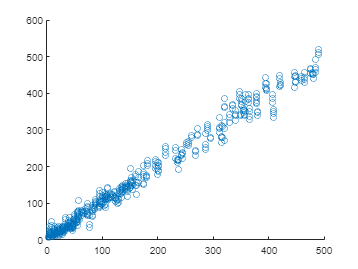


%display target vs pred
figure()
scatter(target.test,pred)

xaiOcc = tcocnnTest2.gradVal(data.test);

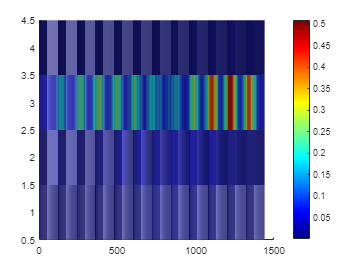

%Movmean in necessary to account for smoth transitions
helpers.ImageDisp(movmean(mean(abs(xaiOcc(:,:,:,:)),4),30,2),data.train(:,:,1,1));

meanResponse = mean(data.train(:,:,1,:),4);
xaiOccMeanId1 = movmean(mean(abs(xaiOcc(:,:,:,:)),4),30,2);
xaiOccMeanId1 = xaiOccMeanId1 <0.1;

dataRed1 = data;
for i = 1:size(dataRed1.train,4)
    temp = squeeze(dataRed1.train(:,:,1,i));
    temp(xaiOccMeanId1) = meanResponse(xaiOccMeanId1);
    dataRed1.train(:,:,1,i) = temp;
end

for i = 1:size(dataRed1.val,4)
    temp = squeeze(dataRed1.val(:,:,1,i));
    temp(xaiOccMeanId1) = meanResponse(xaiOccMeanId1);
    dataRed1.val(:,:,1,i) = temp;
end

for i = 1:size(dataRed1.test,4)
    temp = squeeze(dataRed1.test(:,:,1,i));
    temp(xaiOccMeanId1) = meanResponse(xaiOccMeanId1);
    dataRed1.test(:,:,1,i) = temp;
end

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest3 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest3.train(dataRed1.train,target.train);
%Predict Test Data
pred = tcocnnTest3.apply(dataRed1.test);
disp(helpers.RMSE.loss(pred,target.test));

   20.0450



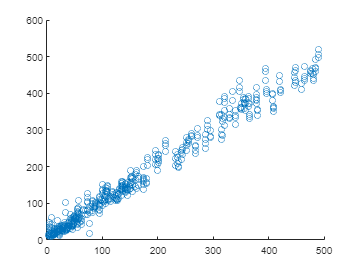


%display target vs pred
figure()
scatter(target.test,pred)

% xaiOcc1 = tcocnnTest3.gradVal(data.test);
% helpers.ImageDisp(mean(abs(xaiOcc1(:,:,:,:)),4),dataRed1.train(:,:,1,1));

meanResponse = mean(data.train(:,:,1,:),4);
xaiOccMeanId2 = movmean(mean(abs(xaiOcc(:,:,:,:)),4),30,2);
xaiOccMeanId2 = xaiOccMeanId2 >0.1;

dataRed2 = data;
for i = 1:size(dataRed2.train,4)
    temp = squeeze(dataRed2.train(:,:,1,i));
    temp(xaiOccMeanId2) = meanResponse(xaiOccMeanId2);
    dataRed2.train(:,:,1,i) = temp;
end

for i = 1:size(dataRed2.val,4)
    temp = squeeze(dataRed2.val(:,:,1,i));
    temp(xaiOccMeanId2) = meanResponse(xaiOccMeanId2);
    dataRed2.val(:,:,1,i) = temp;
end

for i = 1:size(dataRed2.test,4)
    temp = squeeze(dataRed2.test(:,:,1,i));
    temp(xaiOccMeanId2) = meanResponse(xaiOccMeanId2);
    dataRed2.test(:,:,1,i) = temp;
end

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest4 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest4.train(dataRed2.train,target.train);
%Predict Test Data
pred = tcocnnTest4.apply(dataRed2.test);
disp(helpers.RMSE.loss(pred,target.test));

   20.0487



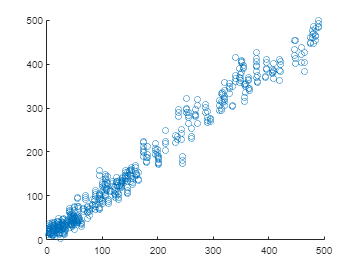


%display target vs pred
figure()
scatter(target.test,pred)

% xaiOcc2 = tcocnnTest4.gradVal(data.test);
% helpers.ImageDisp(mean(abs(xaiOcc2(:,:,:,:)),4),dataRed2.train(:,:,1,1));